# Branch Logic

[⇦ Overview](matlab: run("OpenOverview.m"))

Computers must be told explicitly how to make decisions. One type of decisions which is common in computer programming is a branch decision. There is a logical statement that controls which of several possible paths through the code will be followed based on the state of the inputs. One common depiction of branch logic is a flow chart, but branching can also describe the options available in navigating a maze.   

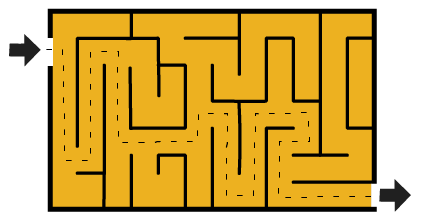

Branches allow you to create flexible code that can react to changing conditions.

**Before you get started:**

This live script is intended to be used with the code visible and output inline. On **View** tab of the MATLAB toolstrip, in the **View** section, select **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

 Interacting with this live script will build some familiarity with MATLAB, as concepts and commands are introduced together, but some familiarity with the Live Editor environment was introduced in [Introduction.mlx](matlab:open('./Introduction.mlx')). A brief summary of the tools, tips, and suggestions from each script is gathered in [Collected Pro Tips](matlab:open('./CollectedProTips.mlx')).

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one, including running all code blocks.

## Branches

In order to navigate the world, you have to make frequent choices. Perhaps you have come to a corner and you must choose between going straight or turning onto a new street. How are you going to make that decision? 

Branching code is frequently visualized with a tree structure, such as depicted here. Run this code block by clicking the    **Run Section** button in the **Live Editor** tab.

drawIfThenTree(2)

  **Pro-tip. **If you would rather stick to the keyboard rather than using the mouse to run the code blocks, you can run the code blocks in the currently selected section by typing Ctrl-Enter together. 

### if/else branches

This type of binary branching depicted by `drawIfThenTree(n)` describes a series of true/false choices that determine a path through a binary tree from the root to a leaf. At each node there is a true/false condition to check. The result of each condition identifies the next edge to follow which specifies a particular option. The number `n` specifies the number of options. 

  **Try**. 

- Sketch the tree you expect for a larger number of options, e.g. with `n=3` and/or `n=4` and/or `n=5`. Then run `drawIfThenTree(n)`. Do the graphs match?

- What happens if `n=1`? Or if `n=10`? You will improve this code in Exercise 2. 

- Write code that will execute `disp("Hello, world!")` if `greetingChoice == "arriving"` and will execute `disp("Goodbye, world!")` if `greetingChoice = "leaving"`. Then run it several times to see that the code follows different paths based on the randomly generated value of `greet`.

options = ["arriving" "leaving"];
greetingChoice = options(randi(2,1))      % Select a random element from options

    The syntax in MATLAB for an if/then conditional is

% Write your code here


 **Reflect**.

- What do you think `disp` does? If you check the documentation, are you correct?

- If `Condition 1` is true, is it possible to keep asking further questions? 

- Can you draw two different decision trees with four outcomes? If so, how do they differ? If not, why not?

 ** Exercise 1. **Write an if/then branching statement that will print an appropriate greeting based on the time of day. You can use the MATLAB function `clock` to determine the time. Remember that to extract the `k`th element of a vector `vec` you need to use index notation `vec(k)`.

% Write your code here 
% Please replace these comments with appropriate ones explaining your
% choices in designing the greeting code



  **Pro-tip**. If you wish to choose between more than two options using an if/then branch, you may want to use the nested if/elseif/else branches depicted for higher values of `n` in `drawIfThenTrees(n)`. The MATLAB syntax is

** Exercise 2**. Make the function `drawIfThenTree(n)` work better.

Modify the function drawIfThenTree(n) by adding a check for whether `n == 1`. If so, execute the following: 

Otherwise, `treeNodes` should be defined as it was originally. You can check your results by running the code at the beginning of this section.

### Switches 

A switch may be an appropriate structure to use if there are a finite number of distinct options that govern the outcome of the condition, such as a traffic light, a dice roll, or a drop-down menu.

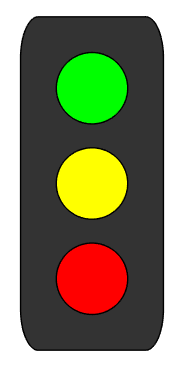                        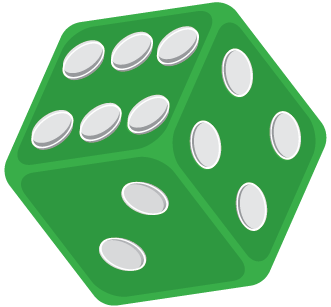

% Choose a value to test this switch statement by causing the code to run
selectedValue = "red"
switch selectedValue
    case "red"
        disp("When the light is red, you should stop.")
    case "green"
        disp("When the light is green, you should go.")
    case "yellow"
        disp("When the light is yellow, you should slow and stop if you can do so safely.")
end

## ** Application of Branches: Chaos Game**

The chaos game is a set of rules that can be applied to many different polygons with varying results. This implementation investigates the chaos game on a square. Beginning at a randomly selected point, at each iteration of the game a new point is selected that is the average of the current point and a randomly selected vertex of the square. Eventually, it will be convenient to be able to easily identify and compare vertices of the square using the map presented:

chaosSquareMap

** Exercise 3**.

Write a switch statement that switches on the variable `newCorner` with the cases `1, 2, 3, `and` 4`. It should set the value of `newCoords` to the appropriate vector in each case, that is `[0,0]` or `[0,1]` or `[1,1]` or `[1,0]`.

% Initialize the value of newCoords to a result it can never have inside
% the square so it is easy to tell if you update it correctly. Suppress the
% output to prevent clutter.
newCoords = [-1 -1]; 

% Randomly select a new corner from the set 1, 2, 3, and 4
newCorner = randi(4,1)      
             
%% Write the switch statement here.

% Run this section to test that the coordinates in newCoords that you get out 
% are what you expect based on the value of newCorner

newCoords

Save this result because you will be using this switch statement a bit later.

### Starting the Chaos Game

Moving on, to start the chaos game, we need to select a starting point. To make the case that the starting point does not impact the eventual results, let's choose that starting point randomly in the code below. The line `startingPoint = rand([1 2])` has been left unsuppressed so you can track the initial value, but feel free to add a semicolon to suppress the output whenever you have convinced yourself that the code works as expected. In fact, it doesn't matter if your random starting point is inside the square or not, but it is a bit easier to visualize what is going on if the initial point is visible. 

  **Try**. Run the code below several times and observe what happens for different values of the `startingPoint`.

startingPoint = rand([1 2])         % Generate a random starting point in the square
s = startChaosGame(startingPoint);

### Taking the Next Step in the Chaos Game

The next step is to randomly select one of the vertices of the square. This code block selects a vertex by number but requires the code you wrote in Exercise 3 to translate that selection into coordinates that can be used to update the chaos game by moving towards the chosen corner. After you have added the switch statement, run this code block at least 4-5 times.

newCorner = randi(4,1)

% Paste the switch statment from Exercise 3 here

s = updateChaosGame(s,newCoords,newCorner);

## More Chaos Game Steps

As you may have noticed, it gets a bit tiresome to add additional points by running the code by hand each time. In [Loops.mlx](matlab:open('./Loops.mlx')), you will learn how to instruct the computer to repeat code on its own. 

[⇦ Overview](matlab: run("OpenOverview.m"))

## Helper Functions

#### drawIfThenTree(n) Function

Follow this link to return to Exercise 2. There is a lot of code in this function that you may not understand immediately, but the comments explain why the code exists. You should read through the entire function at least once before you complete Exercise 2.

function drawIfThenTree(n)
% This function takes an argument n giving the number of options and
% creates an if/then tree depicting choosing between them based on an
% appropriate number of conditions.

%% Code for Exercise 2 goes here


    %% This code generates acceptable trees for values of n > 1

    % Set up the connections between nodes
    treeNodes = zeros(1,2*n-1);
    treeNodes(1) = 2;
    for k = 3:2*n-2
        treeNodes(k) = treeNodes(k-2)+2;
    end
    treeNodes(end) = treeNodes(end-2);

    % Plot the tree and extract the coordinates of the nodes
    treeplot(treeNodes)
    [x,y] = treelayout(treeNodes);

    % Set up the labels on the tree

    % preallocate a 2n-1 vector of strings for efficiency
    treeLabel = strings(1,2*n-1);

    % Label the root node
    treeLabel(1:2) = ["Option 1","if Condition 1"];

    % Walk through each of the elseif decision points and label them
    for k = 2:n-1
        treeLabel(2*k-1:2*k) = ["Option "+k, "elseif Condition "+k];
    end

    % Label the final leaf, the outcome if every condition is false
    treeLabel(2*n-1) = "else Option "+n;
    text(x+.02,y,treeLabel,"FontWeight","bold")

    % Calculate the locations for the "True" and "False" labels and then
    % print them on the figure
    yOdd = (y(1:2:2*n-2)+y(2:2:2*n-2))/2;
    yEven = (y(2:2:2*n-2)+[y(4:2:2*n-2),y(end)])/2;
    yVals = zeros(1,2*n-2);
    yVals(1:2:2*n-2) = yOdd;
    yVals(2:2:2*n-2) = yEven;
    xSkip = zeros(size(yVals));
    xSkip(1:2:end) = -0.07;
    % Note: The choice of 0.03*n as the initial even xSkip value is an approximation
    %       It works well for n in [2,6], but then it begins to fail.
    xSkip(2:2:end) = linspace(0.03*n,0.02,(n-1));
    xVals = repmat("True",size(xSkip));
    xVals(2:2:end) = "False";
    text(x(1:end-1)+diff(x)/2+xSkip,yVals,xVals,"FontSize",8,"Color","blue")
    % This tree is much easier to read without a visible axis
    axis off
    % And zoomed in to fill the available space
    xlim([max(.1,.5-n/10) min(1,.6+n/10)])
    ylim([max(.1,.5-n/10) min(.9,.5+n/10)])
    %% This is the end of the tree-generation code for n > 1

%% Code for Exercise 2 goes here, too

%%

end


#### Image generation code

This code is purely informational. Many of the figures that you encounter throughout these scripts are created in MATLAB. Here is the code that generates several of the images used in this script such as the traffic light. 

function trafficlight %#ok<DEFNU> 
% This function generates an image of a traffic light oriented vertically
% with a red light above a yellow light above a green light.

figure

% With Curvature of [0 0] these commands would give rectangles, with
% positive values of Curvature the corners are rounded
rectangle("Position",[0 0 3 7],"Curvature",[.25 .25],"FaceColor",[.2 .2 .2])
rectangle("Position",[.75 4.75 1.5 1.5],"Curvature",[1 1],"FaceColor","red")
rectangle("Position",[.75 .75 1.5 1.5],"Curvature",[1 1],"FaceColor","green")
rectangle("Position",[.75 2.75 1.5 1.5],"Curvature",[1 1],"FaceColor","yellow")
ylim([-.1 7.1])
xlim([-2.1 5.1])

% This figure is prettier when drawn with equal measurements along both the
% x and y axes, but without the axes showing
axis square off
end

function chaosSquare
% This function generates the annotated image of the square board for the
% Chaos Game where each corner is labeled with only its integer label

figure
rectangle("Position",[0 0 1 1],"Curvature",[0 0])
xlim([-0.2,1.2])
ylim([-0.2,1.2])
text(-0.05,-0.05,"1")
text(-0.05,1.05,"2")
text(1.02,1.05,"3")
text(1.02,-0.05,"4")

% This figure is prettier when drawn with equal measurements along both the
% x and y axes, but without the axes showing
axis square off
end

function data = startChaosGame(startingPoint)
% The function startChaosGame takes one input value, the startingPoint
% coordinates and it returns one value, data, which contains information
% about the structure of the game and how to draw it

chaosSquare                         % Draw the board on which this game will be played
hold on                             % Continue drawing on this figure

% Graph and label the starting point. Note the coordinate shift by 0.02 in
% the x direction for readibility. 
s = scatter(startingPoint(1),startingPoint(2),"o","filled");
t = text(s.XData+0.02,s.YData,"Starting Point");
hold off
c = copyobj(s,s.Parent);   % Create a scatter plot object to identify the selected corner
l = copyobj(s,s.Parent);   % Create a scatter plot object to identify the last point

% Save the information about the game to be used in updateChaosGame later
data = struct('s',s,'t',t,'c',c,'l',l);
end

function data = updateChaosGame(data,newCoords,newCorner)
% The function updateChaosGame takes two inputs, the data generated by
% startChaosGame and the coordinates newCoords identifying the newly chosen vertex
% It returns an updated value of data containing information about the
% current state of the game

% In the annotation space coordinates, the corners of the square have
% x = .3 or x = .735 and y = .23 or y = .81. Shift the coordinates to
% account for the transformation by (x-coords)*(.735-.3)+.3 and
% (y-coords)*(.81-.23)+.23
annotation("arrow",[data.s.XData(end) (data.s.XData(end)+newCoords(1))/2]*.435+.3, ...
    [data.s.YData(end) (data.s.YData(end)+newCoords(2))/2]*.58+.23)

% Add the new points to the scatter plot
data.l.XData = data.s.XData(end);
data.l.YData = data.s.YData(end);
data.l.MarkerFaceColor = "g";

% Determine how to shift the text to stay away from the new arrow. 
switch newCorner
    case 1
        xShift = 0.03;
        yShift = 0.06;
    case 2
        xShift = 0.03;
        yShift = -0.06;
    case 3
        xShift = 0.03;
        yShift = -0.06;
    case 4
        xShift = 0.03;
        yShift = 0.06;
end

% Update the text printed next to the data points based on how many steps
% into the game you currently are. After the third move, assume the player
% understands the structure and doesn't need additional labels cluttering
% the game board
switch length(data.s.XData)
    case 1
        data.t.String = ["From here move halfway" "towards the corner"];
        data.t.Position = [data.s.XData(end) data.s.YData(end) 0] + [xShift yShift 0];
    case 2
        data.t.String = "Now start here";
        data.t.Position = [data.s.XData(end) data.s.YData(end) 0] + [xShift yShift 0];
    case 3
        data.t.String = "And now here, etc.";
        data.t.Position = [data.s.XData(end) data.s.YData(end) 0] + [xShift yShift 0];
    otherwise
        data.t.String = "";
end

% Add the new information to the data structure
data.s.XData = [data.s.XData (data.s.XData(end)+newCoords(1))/2];
data.s.YData = [data.s.YData (data.s.YData(end)+newCoords(2))/2];
data.c.XData = newCoords(1);
data.c.YData = newCoords(2);
data.c.MarkerFaceColor = "r";
end

function chaosSquareMap
% This function generates the annotated image of the square board for the
% Chaos Game where each corner is labeled with both its integer label and
% its coordinate values for reference

figure
rectangle("Position",[0 0 1 1],"Curvature",[0 0])

% Label each corner with its corresponding value
text(-0.05,-0.05,"1")
text(-0.05,1.05,"2")
text(1.02,1.05,"3")
text(1.02,-0.05,"4")

% Label each corner with its corresponding coordinates
text(.02,.05,"(0,0)")
text(.02,.97,"(0,1)")
text(.87,.97,"(1,1)")
text(.87,.05,"(1,0)")

% Set the range and domain for the viewing window
xlim([-0.2,1.2])
ylim([-0.2,1.2])

% This figure is prettier when drawn with equal measurements along both the
% x and y axes, but without the axes showing
axis square off
end



